# Pi Cam

This is a simple color object tracking USB camera tutoria for your robts.

Available USB webcam functions:

- webcamlist - List of webcams connected to your system

- webcam - Connection to a webcam

- preview - Preview live video dta from webcam

- snapshot - Acquire single image frame from a webcam

- closePreview - Close webcam preview window

Simrun Mutha and Jackie Zeng

clc % clear command window
clear % clear MATLAB workspace
imaqreset % clear all iamge objects

**Set up robot control system **

% Connect to raspi
    robotPi = raspi('192.168.16.71')

robotPi =   raspi with properties:

         DeviceAddress: '192.168.16.71'               
                  Port: 18734                         
             BoardName: 'Raspberry Pi Model B+'       
         AvailableLEDs: {'led0'}                      
  AvailableDigitalPins: [4,5,6,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27]
  AvailableSPIChannels: {'CE0','CE1'}                 
     AvailableI2CBuses: {'i2c-1'}                     
      AvailableWebcams: {'bcm2835-isp (platform:bcm2835-isp)','mmal service 16.1 (platform:bcm2835-v4l2)'}
           I2CBusSpeed: 100000                        

  Supported peripherals


% Create connection to the V2 Pi Camera
    robotCam = cameraboard(robotPi, 'Resolution', '1280x720')

robotCam =   cameraboard with properties:

                    Name: Camera Board   
              Resolution: '1280x720'      (View available resolutions)
                 Quality: 10              (1 to 100)
                Rotation: 0               (0, 90, 180 or 270)
          HorizontalFlip: 0              
            VerticalFlip: 0              
               FrameRate: 30              (2 to 90)
               Recording: 0              

   Picture settings
              Brightness: 50              (0 to 100)
                Contrast: 0               (-100 to 100)
              Saturation: 0               (-100 to 100)
               Sharpness: 0               (-100 to 100)

   Exposure and AWB
            ExposureMode: 'auto'          (<a href="matlab

    
% Fix auto exposure problem set it to manual, set exposure to work in lab
% lighting. Set whitebalance to manual too. Auto exposure and white balance
% drive computer vision algorithm crazy
    SETUPPICAMERA(robotCam);

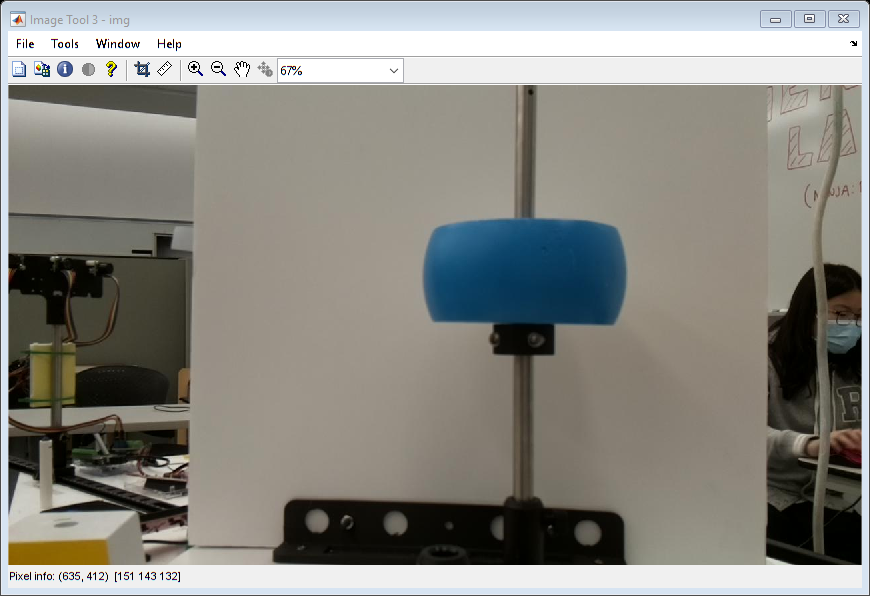


% Acquire a frame
img = snapshot(robotCam);

% Display the frame in the imaqtool window
imtool(img);

%explore image with tool
%gCamTest = input('experiment with tool, type G, then hit ENTER ','s');

clc;

%create a free floating figure for images
picamWindow = figure('name','Robot Pi Camera','NumberTitle','off','Visible','on');
figure(picamWindow) % got to camWindow for imshow
imshow(img,'Border','tight')

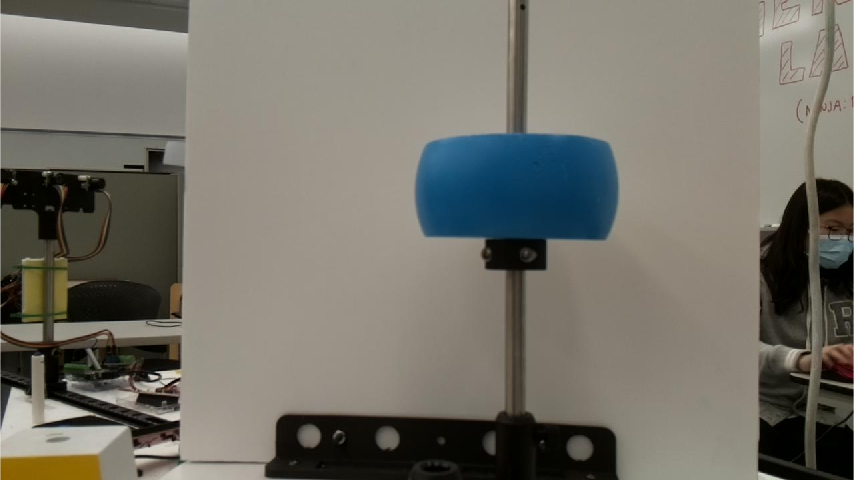

% Save file
filename = input('Input color of object:','s');
saveas(gcf, filename)

**Run Robot Control Loop **

controlFlag = 1;
nTests = 1

nTests = 1

r = rateControl(0.1);
reset(r);

while (controlFlag < nTests +1)
    
    %SENSE finds centroid and area of target
    camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
    [centroids, targetArea] = SENSE(robotCam, camWindow)
    THINK();
    ACT();
    
    %pause to allow you to move objects
    camtest = input('move objects to new position, type G, then hit ENTER', 's');
    clc;
    
    waitfor(r);                         % wait for loop cycle to complete
    controlFlag = controlFlag +1;       % increment loop
end

cleanImage = 720×1280 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

Error using figure
Argument must be a Figure object or a positive integer.

Error in PiCam>SENSE (line 85)
figure(camWindow)

**Clean Shut Down**

% Stop program and clean up connection to WebCam when no longer needed

    clc
    clear robotCam
    disp('SimpleUSBCameraTutorial Done');
    
    beep

**Sense Functions**

function [] =  SETUPPICAMERA(robotCam)    
    % Fix expose to set it to respond quickly, set whitebalance to off
    robotCam.ExposureMode = 'night';
    robotCam.AWBMode = 'fluorescent';
end

function [centroids, targetArea] = SENSE(robotCam, camWindow)
% This function acquires a single image from the USBCamera testCam and
% finds and returns centroids of purple area in image

% capture image
robotImage = snapshot(robotCam);

% use color threshold app to create a colormask funciton ( purplemaks)
% functions will have different anems depending on color of traget
[targetMask, Img] = redMask(robotImage);
camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
figure(camWindow)
imshow(targetMask)
camtest = input('check out masked image,type G, hit Enter','s');
clc;

% Preprocess image to remove noise
se = strel('disk',50);
cleanImage = imopen(targetMask, se) %structure element erosion function
camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
figure(camWindow)
imshow(cleanImage)
camtest = input('check out cleaned image, type G, then hit enter',"s")
clc;

%calculate the centroid of the white part of masked area(target)
targetCenter = regionprops(cleanImage,'centroid');
%store the x and y coordinates in a two column matrix
centroids = cat(1,targetCenter.Centroid);
% Display the original image with the centroid locations superimposed
camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
figure(camWindow) % go to camWindow for imshow
imshow(robotImage)
hold on
plot(centroids(:,1),centroids(:,2),'b*')
text(centroids(:,1),centroids(:,2), 'Target Centroid')
hold off
camtest = input('check out target center, type G, and hit enter','s');
clc;

% Calculate the area of the target
targetArea = regionprops(cleanImage,'area');
area = targetArea.Area;
% Store the x and y coordinates in a two column matrix
centroids = cat(1,targetCenter.Centroid);
% Display the binary image with the centroid locations superimposed
camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
figure(camWindow) % go to camWindow for imshow
imshow(robotImage)
hold on
plot(centroids(:,1),centroids(:,2),'b*')
%plot(centroids(:,1),(centroids(:,2) + 10),num2str(area));
hold off
camtest = input('check out target center, type G, and hit enter','s');
clc
end

function THINK()
    % null
end

function ACT()
    % null
end